# Improving the bandwidth

At this point we have validated the model and verified that the original controllers work. For some reason the VRFT tool fails to provide satisfactory results for the inner controller but that should not be an issue if we simply use the original parameters. 

To avoid depending on a mountain of external code we'll refine the important bits here

PitchRateModel = tf(.4323,  [1, 1.334]);
Ri = pid(.3, .3, .05, .01);
Mixer = 66.6667;

InnerLoop = loopsens(PitchRateModel * Mixer, Ri); 

Ro = pid(1.61, 0, .00512, .01); 
integrator = tf(1, [1, 0]);

PlantModel = InnerLoop.Ti * integrator; 
OuterLoop = loopsens(PlantModel, Ro); 

% Question: Run minreal on InnerLoop.Ti too ?

Now we want to improve the performance of the outer loop. 

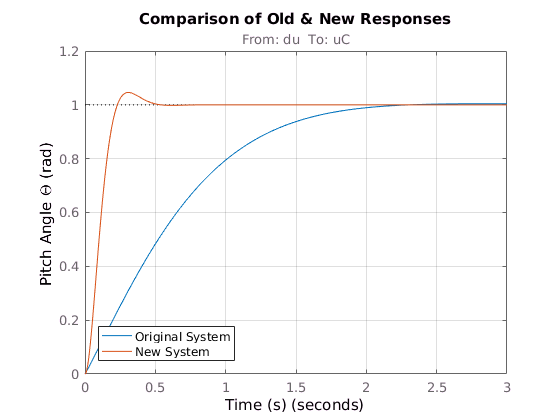

Ta    = .5;  % Settling Time, seconds
zeta  = .7; % Desired damping. 
omega =  5 / (zeta * Ta);  % Desired bandwidth 

mk_2nd_order = @(omega, zeta) tf(omega^2, [1, 2*omega*zeta, omega^2]);
TargetReferenceModel = mk_2nd_order(omega, zeta);

% To validate the new model we use the series of increasing step defined in 
% |quad_copter_model.mlx| (Section: Testing Our Model)
% original_theta = lsim(OuterLoop.Ti, test_theta_set_point, test_time_vec);
% new_theta      = lsim(TargetReferenceModel, test_theta_set_point, test_time_vec);
% 
% figure()
%     plot(test_time_vec, test_theta_set_point, '--', ...
%          test_time_vec, original_theta, test_time_vec, new_theta);  
%     title('Comparison of Old & New Responses'); 
%     legend('Set-Point', 'Original System', 'New System', 'location', 'SouthWest');
%     xlabel('Time (s)'); ylabel('Pitch Angle \Theta (rad)');

step(OuterLoop.Ti, TargetReferenceModel); 
title('Comparison of Old & New Responses'); 
legend('Original System', 'New System', 'location', 'SouthWest');
xlabel('Time (s)'); ylabel('Pitch Angle \Theta (rad)'); grid on; 

If the response plot looks good enough we need to see what VRFT can do with it. 

To run the VRFT we will need to discretize the models we have so far: 

Ts = .01; 
TargetReferenceModel_dt = c2d(TargetReferenceModel, Ts);

% Are these discretizations needed ? We use InnerLoop.Ti to discretize
% PitchRateModel_dt = c2d(PitchRateModel, Ts);
% Ri_dt = c2d(tf(Ri), Ts);
InnerLoop_dt = tf(minreal(c2d(InnerLoop.Ti, Ts), .025));

1 state removed.


First off we need to generate the I/O data for the outer loop. We collapse the inner loop into one block and integrate it. This is the outer 'plant' model. 

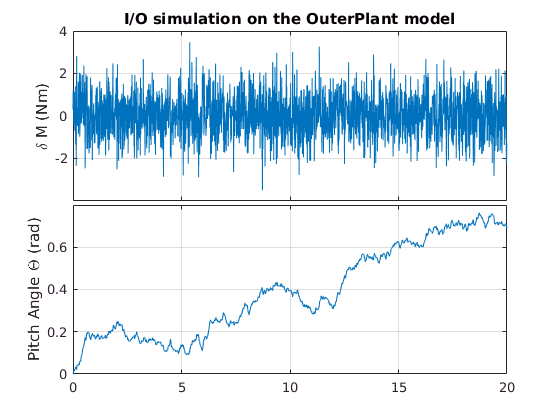

OuterPlant = InnerLoop.Ti * integrator;
OuterPlant_dt = c2d(OuterPlant, Ts);

N = 2000;
time = [0:(N-1)] * Ts;

u = wgn(N, 1, 0);
y = lsim(OuterPlant_dt, u, time); 

figure()
    subplot 211; 
        plot(time, u); ylabel('\delta M (Nm)');
        title('I/O simulation on the OuterPlant model');
    subplot 212;
        plot(time, y); ylabel('Pitch Angle \Theta (rad)');

condense_subplots('tight', true);

Next we need a controller family. A PD controller is  imposed on us so no thinking here. 

Tf = .1;
ControllerClass = [ 1, tf([1 0], [Tf 1]) ].';
ControllerClass_dt = c2d(ControllerClass, Ts);

Now we run the VRFT 

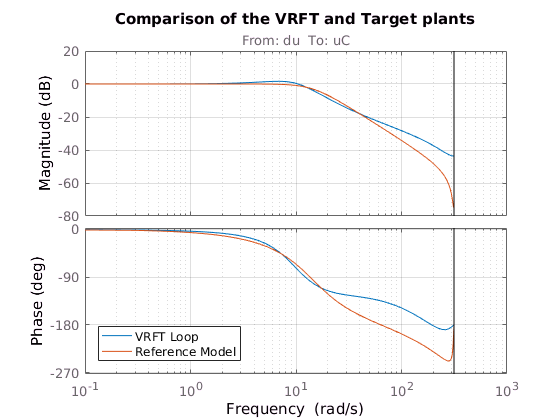

[HybridVRFTController, Theta] = ...
    VRFT1_ry_theta(u, y, TargetReferenceModel_dt, ControllerClass_dt, [], [], []);

HybridLoop = loopsens(OuterPlant_dt, HybridVRFTController); 

figure()
    bode(HybridLoop.Ti, TargetReferenceModel_dt);
    legend('VRFT Loop', 'Reference Model', 'Location', 'southWest');
    title('Comparison of the VRFT and Target plants');
    grid on;

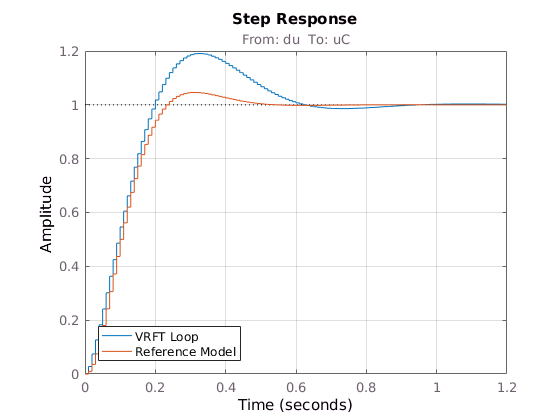

    
figure()
    step(HybridLoop.Ti, TargetReferenceModel_dt);
    legend('VRFT Loop', 'Reference Model', 'Location', 'southWest');
    grid on;